## Mitigation Scenarios 

load('data/windfarms_processed.mat')
load('data/energy_processed.mat');
load('data/birdAtRisk.mat')
load('data/2018/Density_estimationMap','g');
%load('data/2018/Density_estimationMap','gd');

Set to zero if nan

birdAtRisk(isnan(birdAtRisk)) = 0;

## Night vs Day

How much energy is produced during the day?

energy_day = nansum(energy(daynight))./nansum(energy(:))

energy_day = 0.4334

nansum(energy(daynight)) % in J

ans = 3.1145e+17

In addition to the energy produced during the day, more energy is produced without risking the birds: 

energy_safe=nansum(energy(birdAtRisk==0))/nansum(energy(:))

energy_safe = 0.5779

## Scenario 1 : Ideal world

We can compare then the reminding power lost by how much bird at risk reduction:

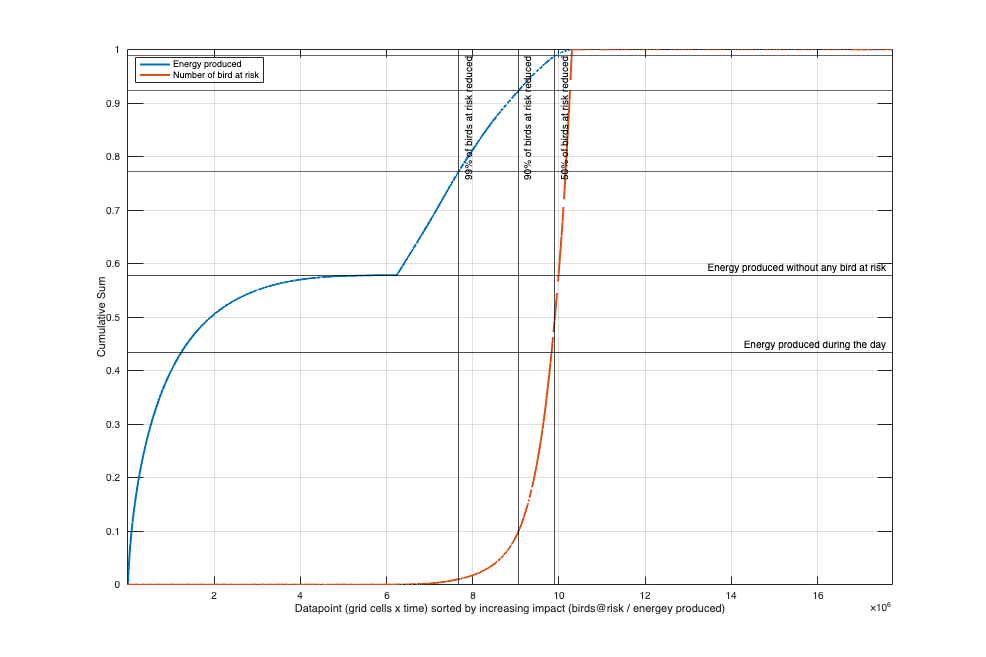

tmp = max(eps, birdAtRisk(:))./energy(:);
[tmp_s,id] = sort(tmp);
id = id(~isnan(tmp_s));
figure('position',[0 0 1200 800]);  hold on; box on; grid on
% plot(tmp_s);
tmp_e = cumsum(energy(id),'omitnan')./nansum(energy(:));
plot(tmp_e,'linewidth',2)   
tmp_b = cumsum(birdAtRisk(id))./nansum(birdAtRisk(:));
plot(tmp_b,'linewidth',2)
yline(energy_day,'-k','Energy produced during the day')
yline(energy_safe,'-k','Energy produced without any bird at risk')
xline(find(tmp_b>.5,1),'-k','50% of birds at risk reduced')
yline(tmp_e(find(tmp_b>.5,1)))
xline(find(tmp_b>.1,1),'-k','90% of birds at risk reduced')
yline(tmp_e(find(tmp_b>.1,1)))
xline(find(tmp_b>.01,1),'-k','99% of birds at risk reduced')
yline(tmp_e(find(tmp_b>.01,1)))
axis tight;
legend('Energy produced','Number of bird at risk','Location','northwest')
ylabel('Cumulative Sum')
xlabel('Datapoint (grid cells x time) sorted by increasing impact (birds@risk / energey produced)')

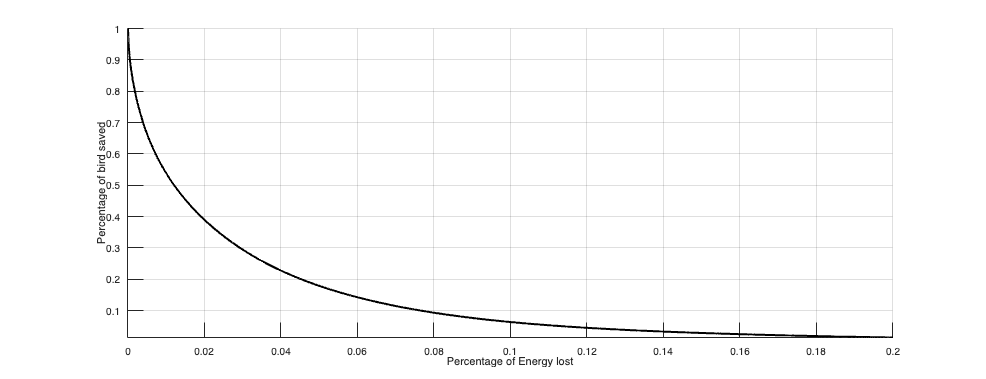

figure('position',[0 0 1300 500]);  hold on; grid on; 
plot((1-tmp_e),tmp_b,'k','linewidth',2);
axis tight; xlim([0 .2])
ylabel('Percentage of bird saved')
xlabel('Percentage of Energy lost')

[~, id1]=min(abs(tmp_b-.1));
[~, id2]=min(abs(tmp_b-.5));
disp("To save 50% of bird at risk, we would loss "+round(100-tmp_e(id2)*100,2)+"% of energy")

To save 50% of bird at risk, we would loss 1.21% of energy


disp("To save 90% of bird at risk, we would loss "+round(100-tmp_e(id1)*100,2)+"% of energy")

To save 90% of bird at risk, we would loss 7.68% of energy


## Scenario 2: Defined migration period

Daily

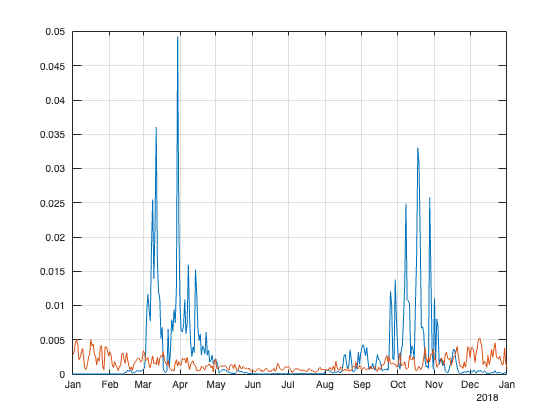

[G,t_day] = findgroups(dateshift(time,'start','day','nearest'));

tmp_b = splitapply( @sum, reshape(sum(sum(birdAtRisk),2),1,[]), G);
tmp_e = energy;
tmp_e(daynight)=0;
tmp_e = splitapply( @nansum, reshape(nansum(nansum(tmp_e),2),1,[]), G);

figure; hold on; box on; grid on
plot(t_day,tmp_b./sum(birdAtRisk(:)))
plot(t_day,tmp_e./nansum(energy(:)))

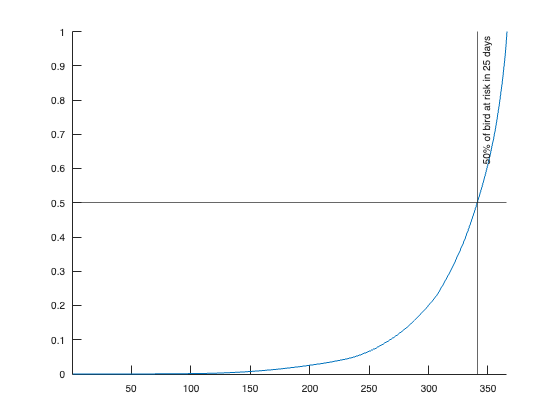

figure; hold on;
y=cumsum(sort(tmp_b))./sum(tmp_b);
plot(y)
yline(.5)
[~,tmp]=min(abs(y-.5));
xline(tmp,'-',['50% of bird at risk in ' num2str(numel(t_day)-tmp) ' days'])
axis tight;

Get 50% or 90% of bird at risk

cs = [0; cumsum(tmp_b)'];
tot = sum(tmp_b);

% thresholds to check
targets = [0.5, 0.9]*tot;

results = struct();

for tt = 1:length(targets)
    target = targets(tt);

    best_len = inf;
    best_idx = [];

    % search all intervals in [40,180] and [180,366]
    for i = 40:180
        for j = i:180
            sum1 = cs(j+1)-cs(i);
            for k = 180:366
                for l = k:366
                    sum2 = cs(l+1)-cs(k);
                    if sum1+sum2 >= target
                        len = (j-i+1)+(l-k+1);
                        if len < best_len
                            best_len = len;
                            best_idx = [i,j;k,l];
                        end
                    end
                end
            end
        end
    end

    results(tt).target = target/tot; % fraction (0.5 or 0.9)
    results(tt).idx = best_idx;
    results(tt).len = best_len;
    results(tt).dates = [t_day(best_idx(1,1)) t_day(best_idx(1,2)); ...
                         t_day(best_idx(2,1)) t_day(best_idx(2,2))];
end

results

results = 1×2 struct array with fields:
    target
    idx
    len
    dates


results.dates

ans = 2×2 datetime array
   04-Mar-2018   08-Apr-2018
   17-Oct-2018   20-Oct-2018


ans = 2×2 datetime array
   03-Mar-2018   02-May-2018
   24-Sep-2018   19-Nov-2018


Off certain Season

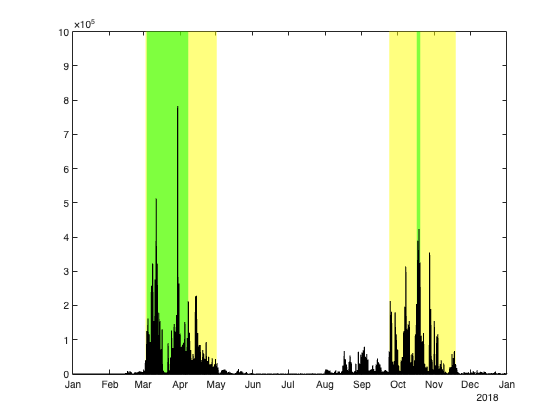

thr_date = datetime({...
    '1-Mar-2018','1-May-2018','15-Aug-2018','15-Nov-2018';...
    '1-Mar-2018','1-Apr-2018','1-Oct-2018','1-Nov-2018';...
    });
% Build thr_date directly from results (2 rows: 90% and 50%)
thr_date = [results(2).dates(1,:) results(2).dates(2,:);  % yellow = 90%
            results(1).dates(1,:) results(1).dates(2,:)]; % green = 50%

figure; hold on
fill([thr_date(1,1) thr_date(1,2) thr_date(1,2) thr_date(1,1)],[0 0 10^6 10^6],'y','EdgeAlpha',0,'FaceAlpha',.5)
fill([thr_date(1,3) thr_date(1,4) thr_date(1,4) thr_date(1,3)],[0 0 10^6 10^6],'y','EdgeAlpha',0,'FaceAlpha',.5)
fill([thr_date(2,1) thr_date(2,2) thr_date(2,2) thr_date(2,1)],[0 0 10^6 10^6],'g','EdgeAlpha',0,'FaceAlpha',.5)
fill([thr_date(2,3) thr_date(2,4) thr_date(2,4) thr_date(2,3)],[0 0 10^6 10^6],'g','EdgeAlpha',0,'FaceAlpha',.5)
plot(time,reshape(sum(sum(birdAtRisk),2),1,[]),'k')
box on


clear tmp_col
tmp_col(1,:) = [nansum(birdAtRisk(:)) nansum(energy(:)) nansum(energy(:).*daynight(:)) nansum(energy(:).*~daynight(:))];
for i_t=1:size(thr_date,1)
    it = ~( (time>thr_date(i_t,1)&time<thr_date(i_t,2)) | (time>thr_date(i_t,3)&time<thr_date(i_t,4)) );
    tmp_col(i_t+1,:) = [nansum(birdAtRisk(:,:,it),'all') nansum(energy(:,:,it),'all') nansum(energy(:,:,it).*daynight(:,:,it),'all') nansum(energy(:,:,it).*~daynight(:,:,it),'all') ];
end
t=table({'No cut','yellow','green'}',tmp_col(:,1),tmp_col(:,2),tmp_col(:,3),tmp_col(:,4),'VariableNames',{'Mitigation','Bird at risk','Energy','Energy day','Energy night'})

t = 3×5 table
    Mitigation    Bird at risk      Energy      Energy day    Energy night
    __________    ____________    __________    __________    ____________

    {'No cut'}     1.1408e+08     7.1863e+17    3.1145e+17     4.0718e+17 
    {'yellow'}     1.2051e+07     4.7334e+17     2.034e+17     2.6993e+17 
    {'green' }     6.0181e+07     6.3434e+17    2.7181e+17     3.6253e+17 


tperc = t(:,1:3);
tperc{:,2}=t{:,2}./t{1,2}*100;

We will assume that energy is only lost during the night

tperc{:,3}=100-(t{1,4} + t{:,5})./t{1,3}*100;
tperc.Properties.VariableNames{'Energy'} = 'Energy loss';
tperc

tperc = 3×3 table
    Mitigation    Bird at risk    Energy loss
    __________    ____________    ___________

    {'No cut'}          100       2.8422e-14 
    {'yellow'}       10.563           19.099 
    {'green' }       52.752           6.2139 


## Scenario 3: Threashold of bird flow

Compute bird saved and energy lost for different threashold of bird flow (bird/m^2/hr)

birdf = logspace(-6,-1,100);
birdAtRisk_saved=nan(size(birdf));
energy_lost=nan(size(birdf));
for i_d=1:numel(birdf)
    id = birdFlow > birdf(i_d);
    birdAtRisk_saved(i_d) = sum(birdAtRisk(id));
    energy_lost(i_d) = sum(energy(id));
end
tmp1 = birdAtRisk_saved./nansum(birdAtRisk(:));
tmp2 = energy_lost./nansum(energy(:));

Plot

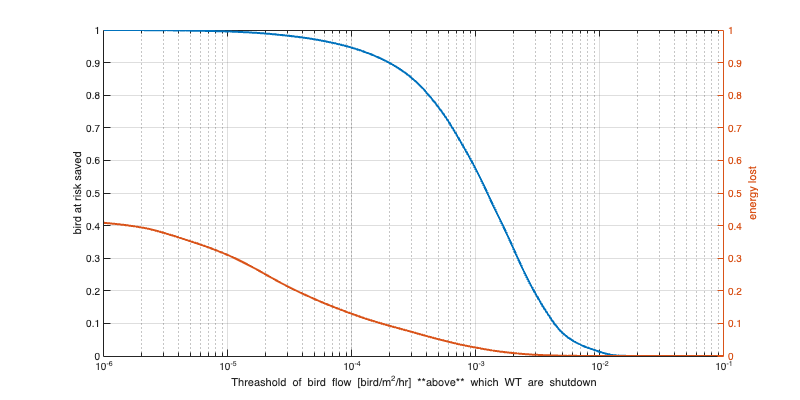

figure('position',[0 0 800 400]); box on; grid on
plot(birdf, tmp1, 'linewidth',2); ylabel('bird at risk saved'); ylim([0 1])
yyaxis right;
plot(birdf, tmp2,'linewidth',2); ylabel('energy lost')
set(gca,'xscale','log'); ylim([0 1]); grid on;
xlabel('Threashold of bird flow [bird/m^2/hr] **above** which WT are shutdown')

Extract energy loss for 50% and 90%

[~, id1]=min(abs(tmp1-.9));
[~, id2]=min(abs(tmp1-.5));
disp("To save 50% of bird at risk, we would need a threshold of "+birdf(id2)+ "bird/m^2/hr resulting in a loss of "+round(tmp2(id2)*100,2)+"% of energy")

To save 50% of bird at risk, we would need a threshold of 0.0012045bird/m^2/hr resulting in a loss of 2.02% of energy


disp("To save 90% of bird at risk, we would need a threshold of "+birdf(id1)+ "bird/m^2/hr resulting in a loss of "+round(tmp2(id1)*100,2)+"% of energy")

To save 90% of bird at risk, we would need a threshold of 0.00018738bird/m^2/hr resulting in a loss of 9.59% of energy


## Scenario: function of energy/per bird saved

Compute bird saved and energy lost for different threashold of bird flow (bird/m^2/hr)

tmp = energy ./ max(eps, birdAtRisk);

eperb_range = logspace(7,12,100);
birdAtRisk_saved=nan(size(eperb_range));
energy_lost=nan(size(eperb_range));
for i_d=1:numel(eperb_range)
    id = tmp < eperb_range(i_d);
    birdAtRisk_saved(i_d) = sum(birdAtRisk(id));
    energy_lost(i_d) = sum(energy(id));
end
tmp3 = birdAtRisk_saved./nansum(birdAtRisk(:));
tmp4 = energy_lost./nansum(energy(:));

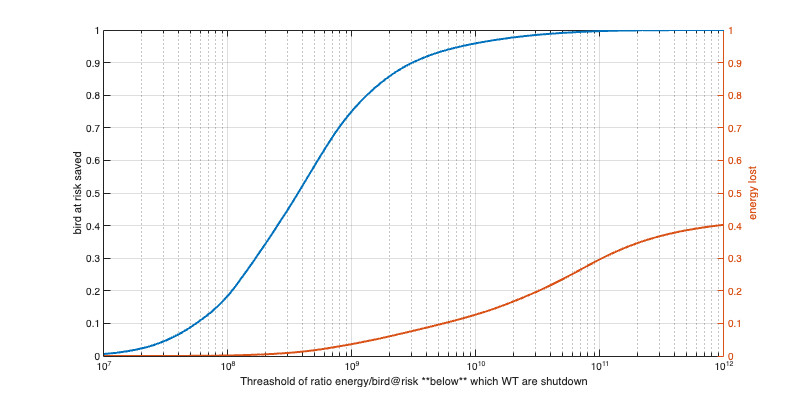

figure('position',[0 0 800 400]); box on; grid on
plot(eperb_range, tmp3 ,'linewidth',2); ylabel('bird at risk saved'); ylim([0 1])
yyaxis right;
plot(eperb_range, tmp4,'linewidth',2); ylabel('energy lost')
set(gca,'xscale','log'); grid on; ylim([0 1])
xlabel('Threashold of ratio energy/bird@risk **below** which WT are shutdown')

Extract energy loss for 50% and 90%

[~, id1]=min(abs(tmp3-.9));
[~, id2]=min(abs(tmp3-.5));
disp("To save 50% of bird at risk, we would need a threshold of "+eperb_range(id2)+ "J/bird*hr resulting in a loss of "+round(tmp4(id2)*100,2)+"% of energy")

To save 50% of bird at risk, we would need a threshold of 367837977.1829J/bird*hr resulting in a loss of 1.21% of energy


disp("To save 90% of bird at risk, we would need a threshold of "+eperb_range(id1)+ "J/bird*hr resulting in a loss of "+round(tmp4(id1)*100,2)+"% of energy")

To save 90% of bird at risk, we would need a threshold of 2983647240.2833J/bird*hr resulting in a loss of 7.57% of energy


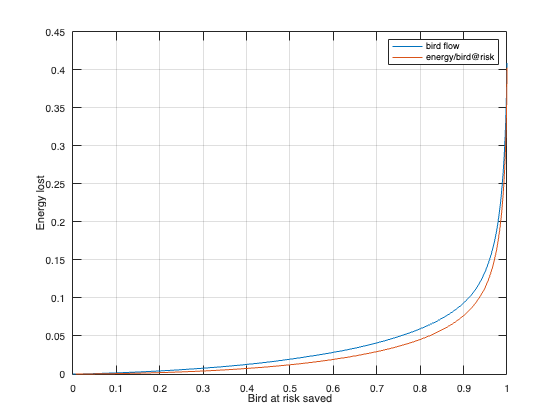

figure; hold on; box on; grid on;
plot(tmp1,tmp2); plot(tmp3,tmp4)
legend("bird flow", "energy/bird@risk")
xlabel("Bird at risk saved"); ylabel("Energy lost")

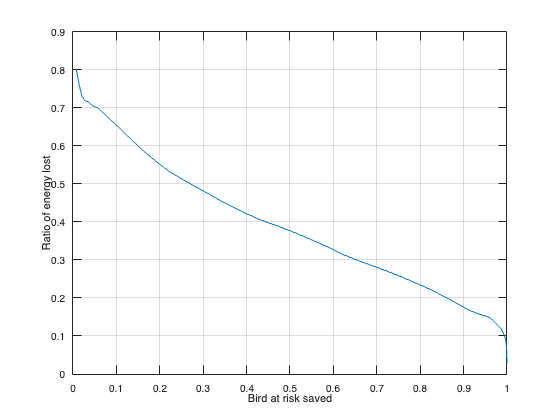

figure; box on; 
plot(tmp1, 1-interp1(tmp3,tmp4,tmp1)./tmp2)
xlabel("Bird at risk saved"); ylabel("Ratio of energy lost")
grid on

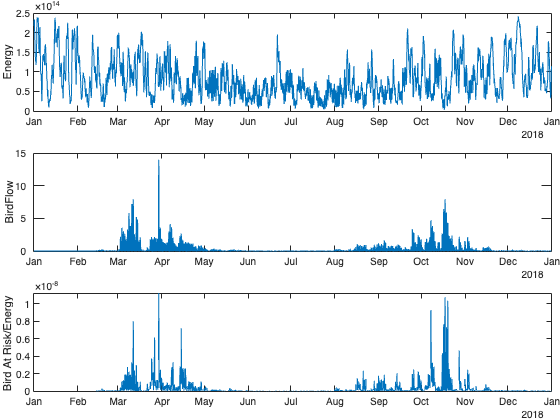


tmp_bf = squeeze(sum(birdFlow,[1 2],"omitnan"));
tmp_bar = squeeze(sum(birdAtRisk,[1 2],"omitnan"));
tmp_e = squeeze(sum(energy,[1 2],"omitnan"));
tmp_epbar = tmp_e ./ max(eps,tmp_bar);
tmp_epbar(isnan(tmp_bf))=nan;
tmp_epbar(tmp_bf==0)=nan;
% tmp_epbar(tmp_bf<0.1)=nan;
figure; tiledlayout('vertical','TileSpacing','tight','Padding','tight');
nexttile; plot(time,tmp_e); ylabel("Energy")
nexttile; plot(time, tmp_bf); ylabel("BirdFlow")
% nexttile; plot(tmp_bar); ylabel("Bird At Risk")
nexttile; plot(time, 1./tmp_epbar); ylabel("Bird At Risk/Energy ")
linkaxes(findall(gcf, 'Type', 'axes'), 'x');

% writetable(table(time', tmp_bf, tmp_e, 1./tmp_epbar, VariableNames=["datetime", "birdflow", "energy" "birdatriskperenergy"]),"temporal_data.csv")

## Scenario 3: Map

Where are the bird at risk during the migration period?

it = ( (time>thr_date(1,1)&time<thr_date(1,2)) | (time>thr_date(1,3)&time<thr_date(1,4)) );
tmp_b = nansum(birdAtRisk(:,:,it),3);
tmp_e = energy(:,:,it);
tmp_n = ~daynight(:,:,it);
tmp_e(~tmp_n) = 0;
tmp_e = nansum(tmp_e,3);

load coastlines
dcoast = pdist2([g.lat2D(:) g.lon2D(:)],[coastlat coastlon], @lldistkm);
dcoast = reshape(min(dcoast,[],2),size(g.lat2D));

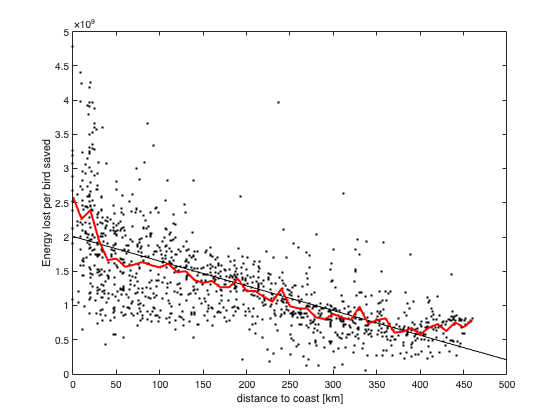

figure; hold on; box on;
plot(dcoast(:), tmp_e(:)./tmp_b(:),'.k'); lsline;
[G,dcoast_bin] = findgroups(round(dcoast(:),-1));
plot(dcoast_bin, splitapply(@nanmean,tmp_e(:)./tmp_b(:),G),'-r','linewidth',2)
xlabel('distance to coast [km]');
ylabel('Energy lost per bird saved')

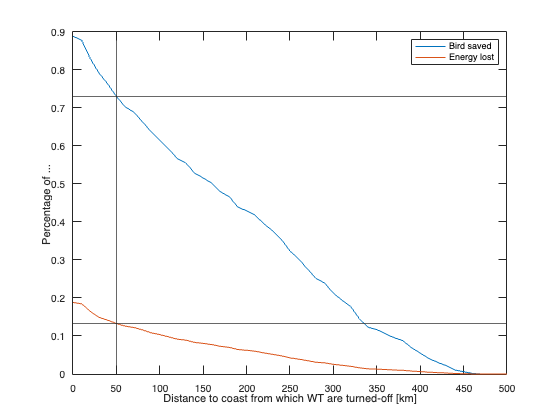

ddd=0:10:500;
tmp_bdd=nan(size(ddd)); tmp_edd=nan(size(ddd));
for i_d=1:numel(ddd)
    tmp_bdd(i_d)=nansum(tmp_b(dcoast>ddd(i_d)))/nansum(birdAtRisk(:));
    tmp_edd(i_d)=nansum(tmp_e(dcoast>ddd(i_d)))/nansum(energy(:));
end
figure; hold on; box on
plot(ddd,tmp_bdd)
plot(ddd,tmp_edd)
xline(50)
yline(tmp_bdd((ddd==50)))
yline(tmp_edd((ddd==50)))
xlabel('Distance to coast from which WT are turned-off [km]');
ylabel('Percentage of ... ')
legend('Bird saved','Energy lost')

figure('position',[0 0 1400 700]); 

ax1=subplot(size(thr_date,1),3,(i_t-1)*3+1); hold on;
h = worldmap([g.lat(1)-2 g.lat(end)+2], [g.lon(1)-2 g.lon(end)+2]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
bordersm('countries','facecolor',[228 238 243]./255);
tmp = tmp_b;
tmp(tmp==0)=nan;
surfm(g.lat,g.lon,tmp)
c=colorbar('south'); title('Birds saved [birds]');
colormap(ax1,brewermap([],'OrRd'))
    
ax2=subplot(size(thr_date,1),3,(i_t-1)*3+2);  hold on;
h = worldmap([g.lat(1)-2 g.lat(end)+2], [g.lon(1)-2 g.lon(end)+2]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
bordersm('countries','facecolor',[228 238 243]./255);
tmp2 = tmp_e;
tmp2(tmp2==0)=nan;
surfm(g.lat,g.lon,tmp2/1e12)
%scatterm(tim.Latitude,tim.Longitude,'.k');
c=colorbar('south'); title('Energy lost [TJ]');
colormap(ax2,plasma)

ax3=subplot(size(thr_date,1),3,(i_t-1)*3+3); hold on;
h = worldmap([g.lat(1)-2 g.lat(end)+2], [g.lon(1)-2 g.lon(end)+2]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
bordersm('countries','facecolor',[228 238 243]./255);
surfm(g.lat,g.lon,tmp2./tmp)
%scatterm(tim.Latitude,tim.Longitude,'.k');
c=colorbar('south'); title('Energy lost per Bird saved [TJ/birds]');
colormap(ax3,viridis)

## Scenario 4: Wind direction

Select only during broad migration

i_t = 1;
it1 = time>thr_date(i_t,1)&time<thr_date(i_t,2);
it2 = time>thr_date(i_t,3)&time<thr_date(i_t,4);

Compute average birdflow direction (weighted by the flow)

% tmp = birdFlow(:,:,it1).*exp(1i*birdDir(:,:,it1));
% mid=nanmean(tmp(:));
% wdir_mean(1) = atan2(imag(mid),real(mid));
% tmp = birdFlow(:,:,it2).*exp(1i*birdDir(:,:,it2));
% mid=nanmean(tmp(:));
% wdir_mean(2) = atan2(imag(mid),real(mid));
% rad2deg(wdir_mean)

Instead, we simplify with,

wdir_mean = deg2rad([45 -135]);

Compute the angle difference between direction of wind and the 45/135°

d = abs(mod(wdir(:,:,it1)-wdir_mean(1)+pi, 2*pi) - pi);
diffit1 = abs(mod(wdir(:,:,it1)-wdir_mean(1)+pi, 2*pi) - pi);
diffit2 = abs(mod(wdir(:,:,it2)-wdir_mean(2)+pi, 2*pi) - pi);
diffit=cat(3,diffit1,diffit2);

Compute as a function of the threashold of angle

tmp_b = birdAtRisk(:,:,it1|it2);
tmp_e = energy(:,:,it1|it2);
tmp_n = ~daynight(:,:,it1|it2);
% only consider night time
tmp_e(~tmp_n) = 0;
dd=0:0.1:pi;
tmp_bdd=nan(size(dd)); tmp_edd=nan(size(dd));
for i_d=1:numel(dd)
    tmp_bdd(i_d) = nansum(tmp_b(diffit < dd(i_d)));
    tmp_edd(i_d) = nansum(tmp_e(diffit < dd(i_d)));
end

Illustrations

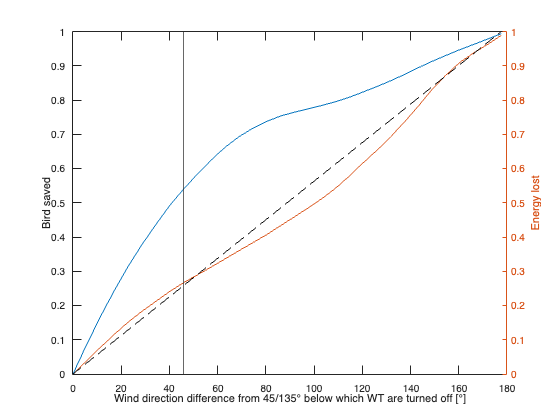

figure; hold on; box on
plot(rad2deg(dd),tmp_bdd./sum(tmp_b(:))); ylabel('Bird saved')
%yline(tmp_bdd((dd==.8)))
yyaxis right; 
plot(rad2deg(dd),tmp_edd./nansum(tmp_e(:)));ylabel('Energy lost')
xline(rad2deg(.8))
plot(rad2deg(dd([1 end])),[0 1],'--k')
%yline(tmp_edd((dd==.8)))
xlabel('Wind direction difference from 45/135° below which WT are turned off [°]');